## Post Hoc Analyses Margulies Gradient & Yeo Networks HCP 

**This script carries out the post hoc analyses that were conducted in the main sample using the margulies gradient and the 7 Yeo networks **

1) Test if maximum *R2 *explained in FC by any of the coupling measures (coupling) is significantly different between uni- and multimodal areas 

2) Test if  coupling strength associated with the region-specific measures for the positive and negative NMA is significantly different between uni- and multimodal areas 

3) Test if assignment of coupling measures in the positive and negative NMA is significantly different between uni- vs. multi-modal brain areas

4) Assign selected coupling measures in the NMAs to the 7 Yeo Networks (VIS, SOM, DA, VA, LIM, FP, DMN) 

Before Running this Script: 

- Run HCP_compute_coupling_measures 

- HCP_NMAs_whole_sample 

- HCP_maximum_variance_explained_all_measures 

**Preparations for the Margulies gradient **

1) Switch RH & LH (to match up with my node ordering)

- negative is unimodal

- positive is multimodal 

rh_parcels = parcel_list(1:180)

rh_parcels = 180×1 cell array
    {'R_V1_ROI'  }
    {'R_MST_ROI' }
    {'R_V6_ROI'  }
    {'R_V2_ROI'  }
    {'R_V3_ROI'  }
    {'R_V4_ROI'  }
    {'R_V8_ROI'  }
    {'R_4_ROI'   }
    {'R_3b_ROI'  }
    {'R_FEF_ROI' }
    {'R_PEF_ROI' }
    {'R_55b_ROI' }
    {'R_V3A_ROI' }
    {'R_RSC_ROI' }
    {'R_POS2_ROI'}
    {'R_V7_ROI'  }
    {'R_IPS1_ROI'}
    {'R_FFC_ROI' }
    {'R_V3B_ROI' }
    {'R_LO1_ROI' }
    {'R_LO2_ROI' }
    {'R_PIT_ROI' }
    {'R_MT_ROI'  }
    {'R_A1_ROI'  }
    {'R_PSL_ROI' }
    {'R_SFL_ROI' }
    {'R_PCV_ROI' }
    {'R_STV_ROI' }
    {'R_7Pm_ROI' }
    {'R_7m_ROI'  }


lh_parcels = parcel_list(181:360)

lh_parcels = 180×1 cell array
    {'L_V1_ROI'  }
    {'L_MST_ROI' }
    {'L_V6_ROI'  }
    {'L_V2_ROI'  }
    {'L_V3_ROI'  }
    {'L_V4_ROI'  }
    {'L_V8_ROI'  }
    {'L_4_ROI'   }
    {'L_3b_ROI'  }
    {'L_FEF_ROI' }
    {'L_PEF_ROI' }
    {'L_55b_ROI' }
    {'L_V3A_ROI' }
    {'L_RSC_ROI' }
    {'L_POS2_ROI'}
    {'L_V7_ROI'  }
    {'L_IPS1_ROI'}
    {'L_FFC_ROI' }
    {'L_V3B_ROI' }
    {'L_LO1_ROI' }
    {'L_LO2_ROI' }
    {'L_PIT_ROI' }
    {'L_MT_ROI'  }
    {'L_A1_ROI'  }
    {'L_PSL_ROI' }
    {'L_SFL_ROI' }
    {'L_PCV_ROI' }
    {'L_STV_ROI' }
    {'L_7Pm_ROI' }
    {'L_7m_ROI'  }



lh_rh_parcels = [lh_parcels; rh_parcels]

lh_rh_parcels = 360×1 cell array
    {'L_V1_ROI'  }
    {'L_MST_ROI' }
    {'L_V6_ROI'  }
    {'L_V2_ROI'  }
    {'L_V3_ROI'  }
    {'L_V4_ROI'  }
    {'L_V8_ROI'  }
    {'L_4_ROI'   }
    {'L_3b_ROI'  }
    {'L_FEF_ROI' }
    {'L_PEF_ROI' }
    {'L_55b_ROI' }
    {'L_V3A_ROI' }
    {'L_RSC_ROI' }
    {'L_POS2_ROI'}
    {'L_V7_ROI'  }
    {'L_IPS1_ROI'}
    {'L_FFC_ROI' }
    {'L_V3B_ROI' }
    {'L_LO1_ROI' }
    {'L_LO2_ROI' }
    {'L_PIT_ROI' }
    {'L_MT_ROI'  }
    {'L_A1_ROI'  }
    {'L_PSL_ROI' }
    {'L_SFL_ROI' }
    {'L_PCV_ROI' }
    {'L_STV_ROI' }
    {'L_7Pm_ROI' }
    {'L_7m_ROI'  }


2) Switch RH & LH (to match up with my node ordering)

rh_gradient = g1(1:180)

rh_gradient =    -3.1719
   -4.2192
   -4.4149
   -3.8302
   -3.7916
   -3.9050
   -4.2432
   -5.0330
   -5.0320
   -1.2599


lh_gradient = g1(181:360)

lh_gradient =    -3.1413
   -3.8190
   -4.4923
   -3.9963
   -4.0355
   -4.1235
   -4.2399
   -5.0644
   -5.0577
   -2.7287



lh_rh_gradient = [lh_gradient; rh_gradient]

lh_rh_gradient =    -3.1413
   -3.8190
   -4.4923
   -3.9963
   -4.0355
   -4.1235
   -4.2399
   -5.0644
   -5.0577
   -2.7287


3) Plot Margulies Gradient 

min(lh_rh_gradient)

ans = -5.2748

max(lh_rh_gradient)

ans = 6.5990

ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [-7 7]
    viewcMap: 1
     viewStr: 'all'


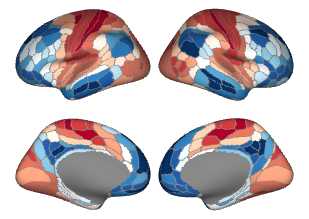

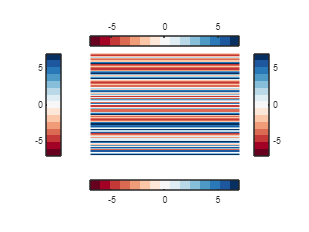

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'hcp-mmp-b';
dataVec = lh_rh_gradient;
parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(15,'RdBu'),...
    'viewcMap',1, 'valRange', ([-7 7]))

1) Test if maximum *R2 *explained in FC by any of the coupling measures (coupling) is significantly different between uni- and multimodal areas 

1.1. Define Variabels

HCP_coupling_only = Mean_values_across_all_nodes_mat_360' % vector describing coupling only in the HCP 

HCP_coupling_only =     0.2315
    0.1254
    0.1915
    0.2410
    0.2415
    0.2612
    0.3101
    0.2875
    0.2573
    0.0529



HCP_coupling_only(isnan(HCP_coupling_only)) = 0

HCP_coupling_only =     0.2315
    0.1254
    0.1915
    0.2410
    0.2415
    0.2612
    0.3101
    0.2875
    0.2573
    0.0529


1.2. Correlation

[r, pval] = corr(lh_rh_gradient,HCP_coupling_only,"type","Pearson")

r = -0.4491

pval = 2.8342e-19

1.3. Spin Permutation

% load PERMS 

x1 = lh_rh_gradient

x1 =    -3.1413
   -3.8190
   -4.4923
   -3.9963
   -4.0355
   -4.1235
   -4.2399
   -5.0644
   -5.0577
   -2.7287


x2 = HCP_coupling_only

x2 =     0.2315
    0.1254
    0.1915
    0.2410
    0.2415
    0.2612
    0.3101
    0.2875
    0.2573
    0.0529


actual_rvalue = r;
nperms = 10000 ; 
null_dist = nan(nperms,1) ;

for idx = 1:nperms;
    null_dist(idx) = corr(x1,x2(PERMS(:,idx)),'type','Pearson');
end

1.4. Check how often random pval is bigger 

count = numel(find(actual_rvalue >= null_dist))

count = 0


perm_pval = (count +1) /(nperms +1)

perm_pval = 9.9990e-05

2) Test if  coupling strength associated with the region-specific measures for the positive and negative NMA is significantly different between uni- and multimodal areas 

2.1. Coupling strength associated with positive NMA 

2.1.1. Define Variabels

HCP_mean_correlation_bcs_pos = Mean_correlation_best_case_scenario_pos_360'

HCP_mean_correlation_bcs_pos =    -0.0609
   -0.1931
   -0.0040
   -0.0589
   -0.1036
   -0.2401
   -0.2870
   -0.0349
   -0.0360
    0.1743


2.1.2. Correlation

[r, pval] = corr(lh_rh_gradient,HCP_mean_correlation_bcs_pos,"type","Pearson")

r = 0.0178

pval = 0.7358

2.1.3. Spin Permutation

% load PERMS 

x1 = lh_rh_gradient

x1 =    -3.1413
   -3.8190
   -4.4923
   -3.9963
   -4.0355
   -4.1235
   -4.2399
   -5.0644
   -5.0577
   -2.7287


x2 = HCP_mean_correlation_bcs_pos

x2 =    -0.0609
   -0.1931
   -0.0040
   -0.0589
   -0.1036
   -0.2401
   -0.2870
   -0.0349
   -0.0360
    0.1743


actual_rvalue = r;
nperms = 10000 ; 
null_dist = nan(nperms,1) ;

for idx = 1:nperms;
    null_dist(idx) = corr(x1,x2(PERMS(:,idx)),'type','Pearson');
end


2.1.4. Check how often random pval is bigger 

count = numel(find(actual_rvalue >= null_dist))

count = 5974

perm_pval = (count +1) /(nperms +1)

perm_pval = 0.5974

2.2. Coupling strength associated with negative NMA 

2.2.1. Define Variabels

HCP_mean_correlation_bcs_neg = Mean_correlation_best_case_scenario_neg_360'

HCP_mean_correlation_bcs_neg =     0.1120
    0.0125
    0.1732
    0.3099
    0.4406
    0.3485
    0.3459
    0.2942
    0.3016
   -0.0267


2.2.2. Correlation

[r, pval] = corr(lh_rh_gradient,HCP_mean_correlation_bcs_neg,"type","Pearson")

r = -0.1092

pval = 0.0383

2.2.3. Spin Permutation

% load PERMS 

x1 = lh_rh_gradient

x1 =    -3.1413
   -3.8190
   -4.4923
   -3.9963
   -4.0355
   -4.1235
   -4.2399
   -5.0644
   -5.0577
   -2.7287


x2 = HCP_mean_correlation_bcs_neg

x2 =     0.1120
    0.0125
    0.1732
    0.3099
    0.4406
    0.3485
    0.3459
    0.2942
    0.3016
   -0.0267


actual_rvalue = r;
nperms = 10000 ; 
null_dist = nan(nperms,1) ;

for idx = 1:nperms;
    null_dist(idx) = corr(x1,x2(PERMS(:,idx)),'type','Pearson');
end

2.2.4. Check how often random pval is bigger 

count = numel(find(actual_rvalue >= null_dist))

count = 912


perm_pval = (count +1) /(nperms +1)

perm_pval = 0.0913

3) Test if assignment of coupling measures in the positive and negative NMA is significantly different between uni-vs. multimodal brain areas 

**3.1. Positive NMA**

% Assignment of the 8 coupling measures to the 4 groups 

% 100 = routing
% 200 = path accessibility 
% 300 = diffusion
% 400 = similarity 


% 1 = Path Length --> 100
% 2 = Communicability --> 300
% 3 = Cosine Distance --> 400
% 4 = Search Information --> 200
% 5 = Path Transitivity --> 200
% 6 = Matching Index --> 400
% 7 = Mean First Passage Time --> 300
% 8 = Flow graphs --> 300



Create a vector that is telling me which brain regions are in which group 

vector = best_performing_measure_per_node_pos_HCP_360_wei % take the original vector 

vector =      5     5     5     5     5     5     5     5     5     3     2     2     5     5     5     1     8     3     5     5     1     1     8     6     6     5     6     5     7     3     4     5     1     8     1     5     6     5     5     5     6     6     5     5     5     5     8     5     6     8



vector(vector == 1) = 100;
vector(vector == 2) = 300;
vector(vector == 3) = 400;
vector(vector == 4) = 200;
vector(vector == 5) = 200;
vector(vector == 6) = 400;
vector(vector == 7) = 300;
vector(vector == 8) = 300;


assignment_coupling_measure_group_pos_NMA = vector

assignment_coupling_measure_group_pos_NMA =    200   200   200   200   200   200   200   200   200   400   300   300   200   200   200   100   300   400   200   200   100   100   300   400   400   200   400   200   300   400   200   200   100   300   100   200   400   200   200   200   400   400   200   200   200   200   300   200   400   300


Run Anova for positive NMA

assignment_coupling_measure_group_pos_NMA([120 300]) = NaN

assignment_coupling_measure_group_pos_NMA =    200   200   200   200   200   200   200   200   200   400   300   300   200   200   200   100   300   400   200   200   100   100   300   400   400   200   400   200   300   400   200   200   100   300   100   200   400   200   200   200   400   400   200   200   200   200   300   200   400   300


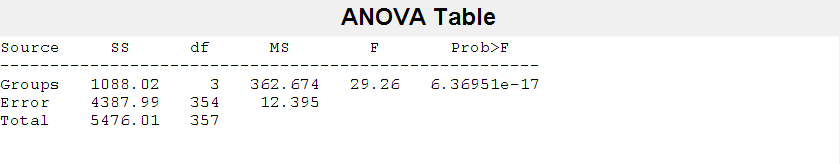

p = 6.3695e-17

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[1.0880e+03]}    {[  3]}    {[362.6737]}    {[ 29.2586]}    {[6.3695e-17]}
    {'Error' }    {[4.3880e+03]}    {[354]}    {[ 12.3954]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[5.4760e+03]}    {[357]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {4×1 cell}
         n: [29 124 97 108]
    source: 'anova1'
     means: [3.3736 -0.1556 1.5491 -2.1993]
        df: 354
         s: 3.5207


[p,tbl,stats] = anova1(lh_rh_gradient,assignment_coupling_measure_group_pos_NMA)

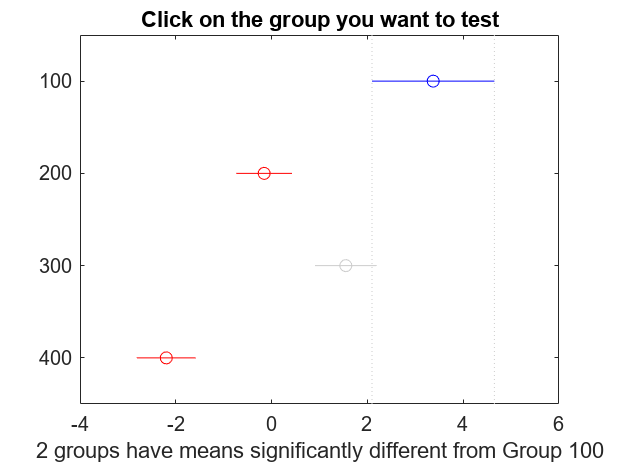

c =     1.0000    2.0000    1.6635    3.5291    5.3948    0.0000
    1.0000    3.0000   -0.0899    1.8244    3.7387    0.0683
    1.0000    4.0000    3.6812    5.5729    7.4646    0.0000
    2.0000    3.0000   -2.9308   -1.7047   -0.4787    0.0020
    2.0000    4.0000    0.8533    2.0437    3.2342    0.0001
    3.0000    4.0000    2.4832    3.7485    5.0137    0.0000


m =     3.3736    0.6538
   -0.1556    0.3162
    1.5491    0.3575
   -2.1993    0.3388


h =   Figure (boxplot) with properties:

      Number: 23
        Name: 'Multiple comparison of means'
       Color: [1 1 1]
    Position: [360 -2 560 420]
       Units: 'pixels'

  Show all properties


gnames = 4×1 cell array
    {'100'}
    {'200'}
    {'300'}
    {'400'}


[c,m,h,gnames] = multcompare(stats)

tbl1 = array2table(c,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl1 = 6×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value  
    _______    _______    ___________    _______    ___________    __________

       1          2          1.6635       3.5291       5.3948      7.0026e-06
       1          3        -0.08985       1.8244       3.7387        0.068297
       1          4          3.6812       5.5729       7.4646      1.7621e-13
       2          3         -2.9308      -1.7047     -0.47871       0.0020076
       2          4         0.85326       2.0437       3.2342      6.0948e-05
       3          4          2.4832       3.7485       5.0137      1.2464e-13


**3.2. Negative NMA**

Create a vector that is telling me which brain regions are in which group 

vector = best_performing_measure_per_node_neg_HCP_360_wei % take the original vector 

vector =      7     7     6     1     2     8     8     4     4     7     7     5     6     8     2     6     4     6     8     6     6     6     6     8     2     6     4     7     6     6     6     4     5     6     6     4     1     1     4     4     1     1     7     2     3     3     7     4     4     7



vector(vector == 1) = 100;
vector(vector == 2) = 300;
vector(vector == 3) = 400;
vector(vector == 4) = 200;
vector(vector == 5) = 200;
vector(vector == 6) = 400;
vector(vector == 7) = 300;
vector(vector == 8) = 300;


assignment_coupling_measure_group_neg_NMA = vector

assignment_coupling_measure_group_neg_NMA =    300   300   400   100   300   300   300   200   200   300   300   200   400   300   300   400   200   400   300   400   400   400   400   300   300   400   200   300   400   400   400   200   200   400   400   200   100   100   200   200   100   100   300   300   400   400   300   200   200   300


Run Anova for negative NMA

assignment_coupling_measure_group_neg_NMA([120 300]) = NaN

assignment_coupling_measure_group_neg_NMA =    300   300   400   100   300   300   300   200   200   300   300   200   400   300   300   400   200   400   300   400   400   400   400   300   300   400   200   300   400   400   400   200   200   400   400   200   100   100   200   200   100   100   300   300   400   400   300   200   200   300


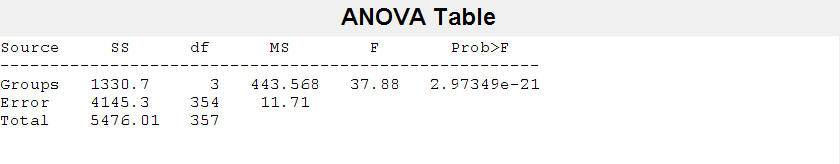

p = 2.9735e-21

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[1.3307e+03]}    {[  3]}    {[443.5678]}    {[ 37.8797]}    {[2.9735e-21]}
    {'Error' }    {[4.1453e+03]}    {[354]}    {[ 11.7099]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[5.4760e+03]}    {[357]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {4×1 cell}
         n: [24 120 130 84]
    source: 'anova1'
     means: [-2.4908 -0.6508 -1.1798 3.3634]
        df: 354
         s: 3.4220


[p,tbl,stats] = anova1(lh_rh_gradient,assignment_coupling_measure_group_neg_NMA)

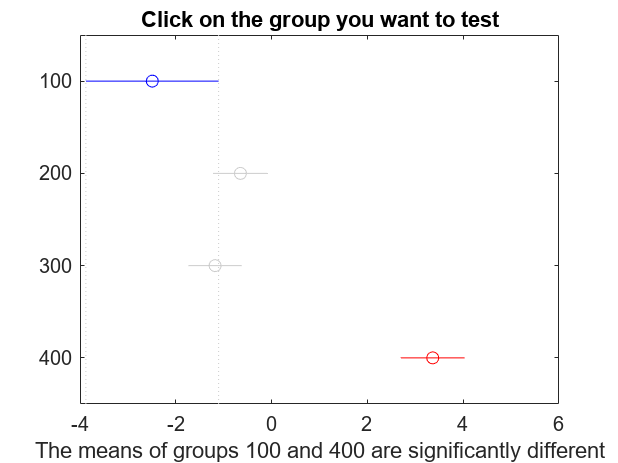

c =     1.0000    2.0000   -3.8058   -1.8400    0.1257    0.0762
    1.0000    3.0000   -3.2642   -1.3110    0.6421    0.3108
    1.0000    4.0000   -7.8890   -5.8542   -3.8195    0.0000
    2.0000    3.0000   -0.5839    0.5290    1.6419    0.6134
    2.0000    4.0000   -5.2648   -4.0142   -2.7636    0.0000
    3.0000    4.0000   -5.7739   -4.5432   -3.3125    0.0000


m =    -2.4908    0.6985
   -0.6508    0.3124
   -1.1798    0.3001
    3.3634    0.3734


h =   Figure (boxplot) with properties:

      Number: 29
        Name: 'Multiple comparison of means'
       Color: [1 1 1]
    Position: [360 -2 560 420]
       Units: 'pixels'

  Show all properties


gnames = 4×1 cell array
    {'100'}
    {'200'}
    {'300'}
    {'400'}


[c,m,h,gnames] = multcompare(stats)

tbl2 = array2table(c,"VariableNames", ...
    ["Group A","Group B","Lower Limit","A-B","Upper Limit","P-value"])

tbl2 = 6×6 table
    Group A    Group B    Lower Limit      A-B      Upper Limit     P-value  
    _______    _______    ___________    _______    ___________    __________

       1          2         -3.8058        -1.84      0.12573        0.076162
       1          3         -3.2642       -1.311      0.64208         0.31085
       1          4          -7.889      -5.8542      -3.8195      7.1941e-13
       2          3         -0.5839        0.529       1.6419         0.61336
       2          4         -5.2648      -4.0142      -2.7636      5.2836e-16
       3          4         -5.7739      -4.5432      -3.3125      1.9921e-21


4) Assign selected coupling measures in the NMAs to the 7 Yeo Networks (VIS, SOM, DA, VA, LIM, FP, DMN)

4.1. Preparation

G2Y = cell2mat(Yeo_Networks_Vectors(:,2))

G2Y = 360×1 single column vector
     1
     3
     1
     1
     1
     1
     1
     2
     2
     3


G2Y = G2Y'

G2Y = 1×360 single row vector
     1     3     1     1     1     1     1     2     2     3     3     7     1     7     6     1     3     1     1     1     1     1     1     2     4     7     7     7     6     7     7     7     7     7     7     2     4     4     2     2     2     3     4     4     3     3     3     3     3     3


Index_VIS = find(G2Y == 1)

Index_VIS =      1     3     4     5     6     7    13    16    18    19    20    21    22    23   121   126   127   142   146   152   153   154   155   156   158   159   160   163   181   182   183   184   185   186   187   193   196   197   198   199   200   201   202   203   301   306   307   322   332   333


Index_SOM = find(G2Y == 2)

Index_SOM =      8     9    24    36    39    40    41    51    52    53    54    55    56   100   101   102   104   107   124   125   139   168   173   174   175   188   189   204   216   219   220   221   231   232   233   234   235   236   279   280   281   282   283   284   287   295   304   305   348   353


Index_DA = find(G2Y == 3)

Index_DA =      2    10    11    17    42    45    46    47    48    49    50    95    96   116   117   136   137   138   141   143   157   190   191   207   222   225   226   227   228   229   230   260   275   276   296   297   316   317   318   320   321   323   326   337


Index_VA = find(G2Y == 4)

Index_VA =     25    37    38    43    44    57    59    60    78    99   103   105   106   108   109   113   114   115   140   147   148   167   169   178   192   205   208   217   218   223   224   237   238   239   240   258   285   286   288   289   292   293   294   319   327   328   347   349   358


Index_LIM = find(G2Y == 5)

Index_LIM =     88    90    92    93   118   122   131   134   135   164   166   172   268   270   272   273   298   302   311   314   315   344   346   352


Index_FP = find (G2Y == 6)

Index_FP =     15    29    58    73    79    80    81    82    83    84    85    86    91    97   111   144   145   171   179   195   209   243   247   253   254   257   259   261   262   263   264   265   266   269   271   277   278   291   313   324   325   329   350   351   359


Index_DM = find (G2Y == 7)

Index_DM =     12    14    26    27    28    30    31    32    33    34    35    61    62    63    64    65    66    67    68    69    70    71    72    74    75    76    77    87    89    94    98   110   112   119   120   123   128   129   130   132   133   149   150   151   161   162   165   170   176   177


4.2. Positive NMA 

Network 1

Measures_in_VIS = best_performing_measure_per_node_pos_HCP_360_wei(Index_VIS)

Measures_in_VIS =      5     5     5     5     5     5     5     1     3     5     5     1     1     8     4     1     5     5     7     8     8     3     4     8     2     5     5     2     5     8     5     5     5     2     3     5     3     3     3     3     7     3     3     8     8     5     5     5     8     5



numel(find(Measures_in_VIS == 1))

ans = 4

numel(find(Measures_in_VIS == 2))

ans = 4

numel(find(Measures_in_VIS == 3))

ans = 12

numel(find(Measures_in_VIS == 4))

ans = 2

numel(find(Measures_in_VIS == 5))

ans = 24

numel(find(Measures_in_VIS == 6))

ans = 0

numel(find(Measures_in_VIS == 7))

ans = 2

numel(find(Measures_in_VIS == 8))

ans = 9

Network 2

Measures_in_SOM = best_performing_measure_per_node_pos_HCP_360_wei(Index_SOM)

Measures_in_SOM =      5     5     6     5     5     5     6     5     5     2     8     5     5     6     3     3     6     6     6     8     8     3     6     6     6     5     5     6     5     5     5     5     5     5     2     5     5     5     6     6     8     6     6     6     6     6     6     8     2     6



numel(find(Measures_in_SOM == 1))

ans = 0

numel(find(Measures_in_SOM == 2))

ans = 3

numel(find(Measures_in_SOM == 3))

ans = 3

numel(find(Measures_in_SOM == 4))

ans = 0

numel(find(Measures_in_SOM == 5))

ans = 20

numel(find(Measures_in_SOM == 6))

ans = 21

numel(find(Measures_in_SOM == 7))

ans = 0

numel(find(Measures_in_SOM == 8))

ans = 5

Network 3

Measures_in_DA = best_performing_measure_per_node_pos_HCP_360_wei(Index_DA)

Measures_in_DA =      5     3     2     8     6     5     5     8     5     6     8     8     6     6     8     6     8     1     8     5     8     5     6     6     6     6     6     6     6     6     3     6     8     5     6     6     8     6     3     6     6     7     3     8



numel(find(Measures_in_DA == 1))

ans = 1

numel(find(Measures_in_DA == 2))

ans = 1

numel(find(Measures_in_DA == 3))

ans = 4

numel(find(Measures_in_DA == 4))

ans = 0

numel(find(Measures_in_DA == 5))

ans = 7

numel(find(Measures_in_DA == 6))

ans = 19

numel(find(Measures_in_DA == 7))

ans = 1

numel(find(Measures_in_DA == 8))

ans = 11

Network 4

Measures_in_VA = best_performing_measure_per_node_pos_HCP_360_wei(Index_VA)

Measures_in_VA =      6     6     5     5     5     6     6     5     6     6     6     6     6     5     6     6     6     6     5     5     5     6     5     6     6     6     6     5     5     5     5     5     6     6     5     6     6     6     6     6     4     6     6     6     6     6     6     5     6



numel(find(Measures_in_VA == 1))

ans = 0

numel(find(Measures_in_VA == 2))

ans = 0

numel(find(Measures_in_VA == 3))

ans = 0

numel(find(Measures_in_VA == 4))

ans = 1

numel(find(Measures_in_VA == 5))

ans = 16

numel(find(Measures_in_VA == 6))

ans = 32

numel(find(Measures_in_VA == 7))

ans = 0

numel(find(Measures_in_VA == 8))

ans = 0

Network 5

Measures_in_LIM = best_performing_measure_per_node_pos_HCP_360_wei(Index_LIM)

Measures_in_LIM =      5     7     1     1     3     8     4     5     8     1     6     4     7     7     5     1     7     8     4     7     8     8     1     8



numel(find(Measures_in_LIM == 1))

ans = 5

numel(find(Measures_in_LIM == 2))

ans = 0

numel(find(Measures_in_LIM == 3))

ans = 1

numel(find(Measures_in_LIM == 4))

ans = 3

numel(find(Measures_in_LIM == 5))

ans = 3

numel(find(Measures_in_LIM == 6))

ans = 1

numel(find(Measures_in_LIM == 7))

ans = 5

numel(find(Measures_in_LIM == 8))

ans = 6

Network 6

Measures_in_FP = best_performing_measure_per_node_pos_HCP_360_wei(Index_FP)

Measures_in_FP =      5     7     8     8     2     4     1     4     1     6     5     5     5     1     8     1     1     1     6     7     5     8     8     5     5     7     5     6     5     5     5     6     5     5     5     8     8     6     7     7     7     1     7     5     6



numel(find(Measures_in_FP == 1))

ans = 7

numel(find(Measures_in_FP == 2))

ans = 1

numel(find(Measures_in_FP == 3))

ans = 0

numel(find(Measures_in_FP == 4))

ans = 2

numel(find(Measures_in_FP == 5))

ans = 15

numel(find(Measures_in_FP == 6))

ans = 6

numel(find(Measures_in_FP == 7))

ans = 7

numel(find(Measures_in_FP == 8))

ans = 7

Network 7

Measures_in_DM = best_performing_measure_per_node_pos_HCP_360_wei(Index_DM)

Measures_in_DM =      2     5     5     6     5     3     4     5     1     8     1     2     8     8     2     5     5     8     1     8     8     1     5     8     8     5     5     8     5     8     1     6     4     6   NaN     6     8     4     4     4     4     1     8     1     8     7     4     5     4     4



numel(find(Measures_in_DM == 1))

ans = 12

numel(find(Measures_in_DM == 2))

ans = 10

numel(find(Measures_in_DM == 3))

ans = 2

numel(find(Measures_in_DM == 4))

ans = 13

numel(find(Measures_in_DM == 5))

ans = 18

numel(find(Measures_in_DM == 6))

ans = 7

numel(find(Measures_in_DM == 7))

ans = 5

numel(find(Measures_in_DM == 8))

ans = 20

4.3. Negative  NMA 

Network 1

Measures_in_VIS = best_performing_measure_per_node_neg_HCP_360_wei(Index_VIS)

Measures_in_VIS =      7     6     1     2     8     8     6     6     6     8     6     6     6     6     7     7     8     2     6     7     7     8     8     6     8     6     4     8     1     7     4     2     8     8     4     4     5     5     5     8     4     5     5     7     2     4     4     4     7     4



numel(find(Measures_in_VIS == 1))

ans = 2

numel(find(Measures_in_VIS == 2))

ans = 4

numel(find(Measures_in_VIS == 3))

ans = 0

numel(find(Measures_in_VIS == 4))

ans = 13

numel(find(Measures_in_VIS == 5))

ans = 6

numel(find(Measures_in_VIS == 6))

ans = 11

numel(find(Measures_in_VIS == 7))

ans = 8

numel(find(Measures_in_VIS == 8))

ans = 13

Network 2

Measures_in_SOM = best_performing_measure_per_node_neg_HCP_360_wei(Index_SOM)

Measures_in_SOM = 1×52
     4     4     8     4     4     4     1     4     3     4     4     4     4     5     7     5     7     4     7     2     7     5     7     8     7     4     4     1     2     8



numel(find(Measures_in_SOM == 1))

ans = 2

numel(find(Measures_in_SOM == 2))

ans = 2

numel(find(Measures_in_SOM == 3))

ans = 1

numel(find(Measures_in_SOM == 4))

ans = 25

numel(find(Measures_in_SOM == 5))

ans = 5

numel(find(Measures_in_SOM == 6))

ans = 0

numel(find(Measures_in_SOM == 7))

ans = 12

numel(find(Measures_in_SOM == 8))

ans = 5

Network 3

Measures_in_DA = best_performing_measure_per_node_neg_HCP_360_wei(Index_DA)

Measures_in_DA = 1×44
     7     7     7     4     1     3     3     7     4     4     7     6     7     7     5     5     6     7     2     8     7     7     2     8     1     8     8     7     1     8



numel(find(Measures_in_DA == 1))

ans = 3

numel(find(Measures_in_DA == 2))

ans = 6

numel(find(Measures_in_DA == 3))

ans = 2

numel(find(Measures_in_DA == 4))

ans = 5

numel(find(Measures_in_DA == 5))

ans = 10

numel(find(Measures_in_DA == 6))

ans = 2

numel(find(Measures_in_DA == 7))

ans = 11

numel(find(Measures_in_DA == 8))

ans = 5

Network 4

Measures_in_VA = best_performing_measure_per_node_neg_HCP_360_wei(Index_VA)

Measures_in_VA = 1×49
     2     1     1     7     2     1     5     8     7     1     8     4     1     8     8     1     8     1     2     7     3     8     7     4     4     5     1     1     1     8



numel(find(Measures_in_VA == 1))

ans = 13

numel(find(Measures_in_VA == 2))

ans = 7

numel(find(Measures_in_VA == 3))

ans = 1

numel(find(Measures_in_VA == 4))

ans = 7

numel(find(Measures_in_VA == 5))

ans = 5

numel(find(Measures_in_VA == 6))

ans = 0

numel(find(Measures_in_VA == 7))

ans = 5

numel(find(Measures_in_VA == 8))

ans = 11

Network 5

Measures_in_LIM = best_performing_measure_per_node_neg_HCP_360_wei(Index_LIM)

Measures_in_LIM = 1×24
     6     6     6     6     2     5     6     2     5     6     8     2     6     6     3     5     6     1     6     3     2     6     4     2



numel(find(Measures_in_LIM == 1))

ans = 1

numel(find(Measures_in_LIM == 2))

ans = 5

numel(find(Measures_in_LIM == 3))

ans = 2

numel(find(Measures_in_LIM == 4))

ans = 1

numel(find(Measures_in_LIM == 5))

ans = 3

numel(find(Measures_in_LIM == 6))

ans = 11

numel(find(Measures_in_LIM == 7))

ans = 0

numel(find(Measures_in_LIM == 8))

ans = 1

Network 6

Measures_in_FP = best_performing_measure_per_node_neg_HCP_360_wei(Index_FP)

Measures_in_FP = 1×45
     2     6     2     6     7     5     6     5     7     8     2     7     2     7     6     5     5     6     1     8     2     5     6     2     7     4     7     5     8     2



numel(find(Measures_in_FP == 1))

ans = 2

numel(find(Measures_in_FP == 2))

ans = 9

numel(find(Measures_in_FP == 3))

ans = 2

numel(find(Measures_in_FP == 4))

ans = 3

numel(find(Measures_in_FP == 5))

ans = 8

numel(find(Measures_in_FP == 6))

ans = 10

numel(find(Measures_in_FP == 7))

ans = 6

numel(find(Measures_in_FP == 8))

ans = 5

Network 7

Measures_in_DM = best_performing_measure_per_node_neg_HCP_360_wei(Index_DM)

Measures_in_DM = 1×89
     5     8     6     4     7     6     6     4     5     6     6     6     6     6     7     6     7     6     6     6     6     6     6     6     6     6     4     6     6     6



numel(find(Measures_in_DM == 1))

ans = 1

numel(find(Measures_in_DM == 2))

ans = 6

numel(find(Measures_in_DM == 3))

ans = 3

numel(find(Measures_in_DM == 4))

ans = 8

numel(find(Measures_in_DM == 5))

ans = 21

numel(find(Measures_in_DM == 6))

ans = 39

numel(find(Measures_in_DM == 7))

ans = 8

numel(find(Measures_in_DM == 8))

ans = 1

Complete Networks

Positive NMA

Measures_complete = best_performing_measure_per_node_pos_HCP_360_wei

Measures_complete = 1×360
     5     5     5     5     5     5     5     5     5     3     2     2     5     5     5     1     8     3     5     5     1     1     8     6     6     5     6     5     7     3



numel(find(Measures_complete == 1))

ans = 29

numel(find(Measures_complete == 2))

ans = 19

numel(find(Measures_complete == 3))

ans = 22

numel(find(Measures_complete == 4))

ans = 21

numel(find(Measures_complete == 5))

ans = 103

numel(find(Measures_complete == 6))

ans = 86

numel(find(Measures_complete == 7))

ans = 20

numel(find(Measures_complete == 8))

ans = 58

Negative NMA

Measures_complete = best_performing_measure_per_node_neg_HCP_360_wei

Measures_complete = 1×360
     7     7     6     1     2     8     8     4     4     7     7     5     6     8     2     6     4     6     8     6     6     6     6     8     2     6     4     7     6     6



numel(find(Measures_complete == 1))

ans = 24

numel(find(Measures_complete == 2))

ans = 39

numel(find(Measures_complete == 3))

ans = 11

numel(find(Measures_complete == 4))

ans = 62

numel(find(Measures_complete == 5))

ans = 58

numel(find(Measures_complete == 6))

ans = 73

numel(find(Measures_complete == 7))

ans = 50

numel(find(Measures_complete == 8))

ans = 41